# Adaptive control for positioning systems

## Adaptive control strategy: ***Self tuning controller***

clear; clc;

**Nominal model initializations**

sqareWaveGen = @(t, T)((t - T*floor(t/T)) < T/2);
Kf0 = 3;
Tf0 = 5;
wn = 1; % closed loop performance parameter
zeta = 1; % closed loop performance parameter
Te = 0.1;
T = 300*Te;
t = 0:Te:5*T;
%u = sqareWaveGen(t, T) - 0.5;
u = sin(t/10);

**Discrete models instantiation**

Hf = tf(Kf0, [Tf0 1 0]);
Hfd = c2d(Hf, Te, 'zoh');
[num, den] = tfdata(Hfd, 'v');
system = LinearDiscreteModel(num(2:end), den, 0);
[num, den] = getDiscreteCompensator(den(2), num(2), Te, wn, zeta);
controller = LinearDiscreteModel(num, den, 0);

**Numeric initialization**

error = zeros(length(u), 1);
output = zeros(length(u), 1);
command = zeros(length(u), 1);
error(1) = u(1);
squaredError = zeros(length(u), 1);

**AAP Initialization**

% model structure parameters
na = 2;
nb = 1;
nd = 1;
windowSize = 300; % observation vector and measurements size
idx = 1;
inputBuffer = zeros(nd, 1);
wY = zeros(windowSize, 1); % measurements
phi = zeros(nb + na + 1, windowSize); % observation vector

% optimizer utility functions
evalCost = @(theta, phi, y)((1/2)*sum((y - theta'*phi).^2));
alpha = 1; % optimizer step
beta = 1.1; % bactracking step increment
alphaUpperThreshold = 10000; % step upper boundary
alphaBottomTreshold = 0.0000001; % step bottom boundary

% paramters vector initialization
[num, den] = tfdata(Hfd, 'v');
[~, theta] = system.getParameters();
theta = [theta theta];

% non-zero intial conditions avoidance
timeUnitsToWait = max(nb + nd, na);
timeUnitsWaited = 0;
isReady = false;

**Variation timing**

f = 1;
changeTime = zeros(2, 1);

## Numeric Simulation

for i = 1:length(u)-1
    error(i) = u(i) - output(i);
    [controller, command(i)] = controller.forward(error(i));
    [system, output(i + 1)] = system.forward(command(i));
          
    if i == floor(length(u)/5) || i == floor(length(u)/2) 
        Kf0 = normrnd(Kf0, 4);
        Tf0 = normrnd(Tf0, 3);
%         Kf0 = Kf0 - 1.4;
%         Tf0 = Tf0 - 1;
        Hf = tf(Kf0, [Tf0 1 0]);
        Hfd = c2d(Hf, Te, 'zoh');
        [num, den] = tfdata(Hfd, 'v');
        system = system.changeParameters(num(2:end), den);
        changeTime(f) = t(i);
        f = f + 1;
    end

    % observation vector update mechanism
    if idx == windowSize
        phi = [phi(:, 2:end) zeros(na + nb + 1, 1)];
        wY = [wY(2:end); 0];
        idx = idx - 1;
    end

    phi(na + 1, idx) = inputBuffer(end);
    inputBuffer = [command(i); inputBuffer(1:end - 1)]; 
    phi(na + 1:end, idx + 1) = [0; phi(na + 1:end - 1, idx)];
    
    phi(1:na, idx + 1) = [-output(i); phi(1:na - 1, idx)];
    wY(idx) = output(i);    
    
    if isReady == false && timeUnitsWaited >= timeUnitsToWait
        isReady = true;
        phi = [phi(:, idx:end) zeros(na + nb + 1, timeUnitsToWait - 1)];
        wY = [wY(idx:end); zeros(timeUnitsToWait - 1, 1)];
        idx = 1;
    end
    
    squaredError(i) = evalCost(theta(:, 1), phi(:, 1:idx), wY(1:idx)');
    if isReady == false
        timeUnitsWaited = timeUnitsWaited + 1;
    else
         % AAP
        theta = AAP(theta, phi(:, 1:idx), wY(1:idx), alpha, beta, alphaUpperThreshold, alphaBottomTreshold);
        
        % auto-tuning the controller
        [num, den] = getDiscreteCompensator(theta(1, 2), theta(3, 2), Te, wn, zeta);
        controller = controller.changeParameters(num, den);
    end
    
    idx = idx + 1;
end

## Results

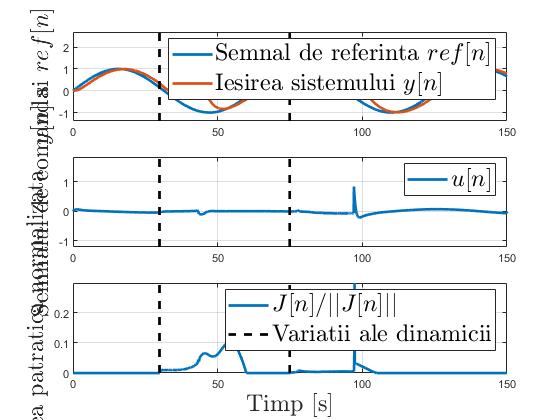

q = -10:Te:10;
lineWidth = 2;
fontSize = 18;

figure,
subplot(3, 1, 1)
plot(t, u, "LineWidth", lineWidth); hold on;
plot(t, output, "LineWidth", lineWidth); grid;
plot(changeTime(1)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
plot(changeTime(2)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
ylabel("$y[n]$ si $ref[n]$", "Interpreter", "latex", "FontSize", fontSize);
legend("Semnal de referinta $ref[n]$", "Iesirea sistemului $y[n]$", ...
    "Interpreter", "Latex", "Location","northeast", "FontSize", fontSize);
axis([0 t(end) min(output)-0.4 max(output)+1.7])

subplot(3, 1, 2)
plot(t, command, "LineWidth", lineWidth); grid; hold on;
plot(changeTime(1)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
plot(changeTime(2)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
ylabel("Semnalul de comanda", "Interpreter", "latex", "FontSize", fontSize);
axis([0 t(end) min(command)-1 max(command) + 1])
legend("$u[n]$", "Interpreter", "Latex", "Location","northeast", "FontSize", fontSize);

subplot(3, 1, 3)
plot(t, squaredError/norm(squaredError), "LineWidth", lineWidth); grid; hold on;
plot(changeTime(1)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
plot(changeTime(2)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
xlabel("Timp [s]", "Interpreter", "latex", "FontSize", fontSize);
ylabel("Eroarea patratica normalizata", "Interpreter", "latex", "FontSize", fontSize);
axis([0 t(end) 0 max(squaredError/norm(squaredError))])
legend("$J[n]/||J[n]||$", "Variatii ale dinamicii", "Interpreter", "Latex", ...
    "Location","northeast", "FontSize", fontSize);

function [num, den] = getDiscreteCompensator(a1, b1, Te, Wn, zeta)
    Tf = -Te/(log(-1 - a1));
    Kf = b1/(Tf*(exp(-Te/Tf) - 1) + Te);
    ca0 = 1 + 1/(zeta*Wn*Te);
    ca1 = 1 - 1/(zeta*Wn*Te);
    cb0 = 1 + 2*Tf/Te;
    cb1 = 1 - 2*Tf/Te;
    num = (Wn/(2*Kf*zeta))*[cb0 cb1];
    den = [ca0 ca1];
    num = num/den(1);
    den = den/den(1);
end